### **Иван Шаламов, 551 группа. ЛР 6 (Распад Произвольного Разрыва), 2021.**

clc;
close all;
clear;
opengl software;

### **Практическая часть.**

Входные параметры.

TextSize = 20;

Gamma = 1.4; % показатель адиабаты
Cp = 1006.43;
R = (Gamma - 1) / Gamma * Cp;

test = 1; % номер теста
[rhoL, uL, pL, rhoR, uR, pR, x_dis, NumCell, t_fin, CFL, ...
    NumTimeStep, BC_L, BC_R] = ShockTubeInitData(test);
TL = pL / (R * rhoL);
TR = pR / (R * rhoR);

plot_interval = 1; % интервал вывода графиков в шагах
NumSmallStep = 0; % количество шагов разгона

OrderInSpace = 1; % порядок аппроксимации по пространству
RiemannSolver = 'Roe'; % 'Exac', 'Roe'
PlotType = 'Rho'; % 'Rho', 'Vel', 'Press', 'IntEnerg', 'Temp', 'RhoV'

Сетка.

nu = 1 ; % коэффициент симметри
x_left = 0; % левая граница
x_right = 1; % правая граница
delta_h = (x_right - x_left) / NumCell;
x_i = (x_left+0.5*delta_h):delta_h:x_right; % центры ячеек

ind_x_dis = floor(x_dis / delta_h); % количество ячеек, поместившихся целиком в x_shock

cut = zeros(1, NumCell);

for i = 1:NumCell
    
    if x_i(i) < 0.335
        
        cut(i) = 1;
        
    elseif x_i(i) > 0.675
        
        cut(i) = 0;
        
    else
        
        cut(i) = (x_i(i) - 0.675) / (0.335 - 0.675);
        
    end
    
end

Переменные.

U1old = zeros(1, NumCell+2);
U2old = zeros(1, NumCell+2);
U3old = zeros(1, NumCell+2);

pLeftInit = 2:ind_x_dis+1;
pRightInit = ind_x_dis+2:NumCell+1;

U1old(pLeftInit) = rhoL;
U1old(pRightInit) = rhoR;

U2old(pLeftInit) = rhoL * uL;
U2old(pRightInit) = rhoR * uR;

U3old(pLeftInit) = pL / (Gamma - 1) + 0.5 * uL^2 * rhoL;
U3old(pRightInit) = pR / (Gamma - 1) + 0.5 * uR^2 * rhoR;

% Граничные условия:
U1old(1) = U1old(2);
U2old(1) = BC_L * U2old(2);
U3old(1) = U3old(2);
U1old(end) = U1old(end-1);
U2old(end) = BC_R * U2old(end-1);
U3old(end) = U3old(end-1);

U1new = U1old;
U2new = U2old;
U3new = U3old;

Временные переменные.

t(1) = 0;
plot_time = plot_interval;

Цикл тестов.

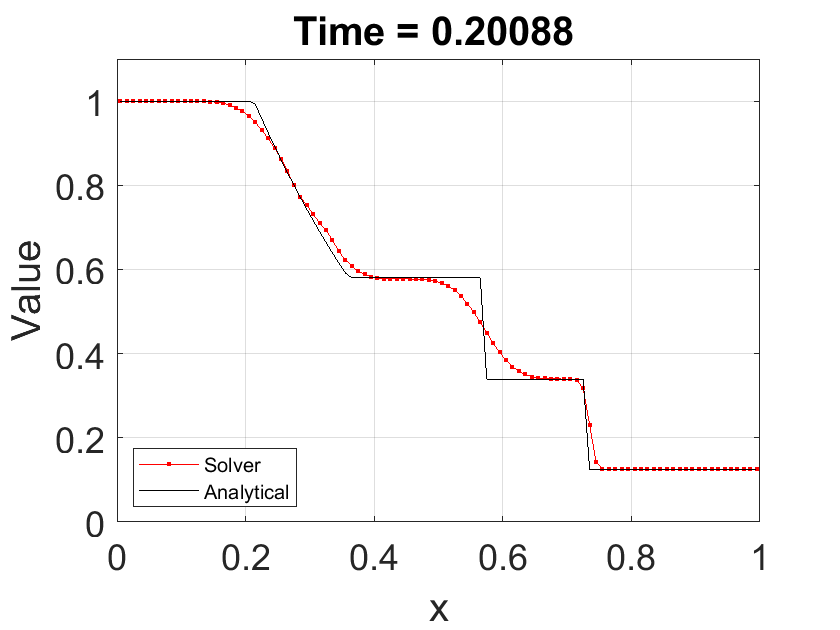

Количество итераций: 60.


for i = 1:NumTimeStep
    
    dt = SolveTimeStepExplicitEiler(U1old, U2old, U3old, delta_h, CFL, Gamma);
    
    if i <= NumSmallStep
        dt = i / NumSmallStep * dt;
    end
    
    t(i+1) = t(i) + dt;
    
    switch (OrderInSpace)
        
        case {1}
            
            switch (RiemannSolver)
                
                case {'Exac'}
                    [F1, F2, F3, iterationExac] = SolveFluxExacRieman(U1old(1:end-1), ...
                        U2old(1:end-1), U3old(1:end-1), U1old(2:end), ...
                        U2old(2:end), U3old(2:end), Gamma); % Godunov
                    
                    if iterationExac > 1
                        disp(iterationExac);
                    end
                    
                case {'Roe'}
                    [F1, F2, F3] = SolveFluxRoe(U1old(1:end-1), U2old(1:end-1), ...
                        U3old(1:end-1), U1old(2:end), U2old(2:end), U3old(2:end), ...
                        Gamma); % Roe
                    
                otherwise
                    [F1, F2, F3, iterationExac] = SolveFluxExacRieman(U1old(1:end-1), ...
                        U2old(1:end-1), U3old(1:end-1), U1old(2:end), U2old(2:end), ...
                        U3old(2:end), Gamma); % Godunov
                    
            end
            
    end
    
    if OrderInSpace > 0
        
        [U1new, U2new, U3new] = SolveEvolutionExplFirstOrder(F1, F2, F3, U1old, ...
            U2old, U3old, nu, dt, delta_h, 0, Gamma);
        
    end
    
    U1old = U1new;
    U2old = U2new;
    U3old = U3new;
    
    % Рассчитываем граничные условия:
    U1old(1) = U1old(2); U1old(end) = U1old(end-1);
    U2old(1) = BC_L * U2old(2); U2old(end) = BC_R * U2old(end-1);
    U3old(1) = U3old(2); U3old(end) = U3old(end-1);
    
    % Конец цикла
    
    if i == plot_time
        
        PlotTestGraphics(1, U1new, U2new, U3new, rhoL, uL, pL, rhoR, uR, pR, ...
            x_i, t, x_dis, Gamma, R, TextSize, test, PlotType);
        plot_time = plot_time + plot_interval;
        
    end
    
    % Выход, если досчитали:
    if t(i+1) > t_fin
        
        PlotTestGraphics(1, U1new, U2new, U3new, rhoL, uL, pL, rhoR, uR, pR, ...
            x_i, t, x_dis, Gamma, R, TextSize, test, PlotType);
        disp(['Количество итераций: ', num2str(i), '.']);
        break;
        
    end
    
end

### **Исследовательская часть.**

Схема Роэ.

function [F1, F2, F3] = SolveFluxRoe(U1L, U2L, U3L, U1R, U2R, U3R, Gamma)

% Переход к консервативным переменным слева и справа:
rhoL = U1L;
uL = U2L./rhoL;
pL = (Gamma - 1) * (U3L - 0.5 * (uL.^2).*rhoL);
cL = sqrt((Gamma * pL./rhoL));
HL = cL.^2 / (Gamma - 1) + uL.^2 / 2;

rhoR = U1R;
uR = U2R./rhoR;
pR = (Gamma - 1) * (U3R - 0.5 * (uR.^2).*rhoR);
cR = sqrt((Gamma * pR./rhoR));
HR = cR.^2 / (Gamma - 1) + uR.^2 / 2;

% Осредненные параметры (Роэ):
u_bar = (sqrt(rhoL).*uL + sqrt(rhoR).*uR)./(sqrt(rhoL) + sqrt(rhoR));
H_bar = (sqrt(rhoL).*HL + sqrt(rhoR).*HR)./(sqrt(rhoL) + sqrt(rhoR));
c_bar = sqrt((Gamma - 1) * (H_bar - 0.5 * u_bar.^2));

% dU = U(R) - U(L) на границах ячеек {x_{i}, x_{i+1}, ...}:
dU1 = U1R - U1L;
dU2 = U2R - U2L;
dU3 = U3R - U3L;

% Потоковые члены слева и справа F_{i+1/2}:
F1L = rhoL.*uL; F2L = rhoL.*uL.^2 + pL; F3L = rhoL.*uL.*HL;
FL = [F1L; F2L; F3L];

F1R = rhoR.*uR; F2R = rhoR.*uR.^2 + pR; F3R = rhoR.*uR.*HR;
FR = [F1R; F2R; F3R];

% Правые собственные вектора:
r1 = [1*ones(1,length(u_bar)); u_bar-c_bar; H_bar-u_bar.*c_bar];
r2 = [1*ones(1,length(u_bar)); u_bar; 1/2*u_bar.^2];
r3 = [1*ones(1,length(u_bar)); u_bar+c_bar; H_bar+u_bar.*c_bar];

% Характеристические приращения:
dw2 = (Gamma - 1)./(c_bar.^2).*(dU1.*(H_bar - u_bar.^2) + u_bar.*dU2 - dU3);
dw1 = 1./(2 * c_bar).*(dU1.*(u_bar + c_bar) - dU2 - c_bar.*dw2);
dw3 = dU1 - (dw1 + dw2);

% Собственные числа:
lambda1 = abs(u_bar - c_bar);
lambda2 = abs(u_bar);
lambda3 = abs(u_bar + c_bar);

lambda1L = uL - cL;
lambda3L = uL + cL;
lambda1R = uR - cR;
lambda3R = uR + cR;

% Искусственная вязкость вблизи звуковой точки:
del = 0.0001;

boolv1 = (lambda1R - lambda1L) > 0;
eps = 2.0 * (lambda1R - lambda1L).*boolv1;
boolv1 = lambda1 < eps;
lambda1 = 0.5 * (eps + (lambda1.^2) / (eps + del)).*boolv1 + lambda1.*(1 - boolv1);

boolv2 = (lambda3R - lambda3L) > 0;
eps = 2.0 * (lambda3R - lambda3L).*boolv2;
boolv2 = lambda3 < eps;
lambda3 = 0.5 * (eps + (lambda3.^2) / (eps + del)).*boolv2 + lambda3.*(1 - boolv2);

% Приведение данных:
dw1 = repmat(dw1, 3, 1);
dw2 = repmat(dw2, 3, 1);
dw3 = repmat(dw3, 3, 1);
lambda1 = repmat(lambda1, 3, 1);
lambda2 = repmat(lambda2, 3, 1);
lambda3 = repmat(lambda3, 3, 1);

% Вычисление потоков (Роэ):
Flux = 0.5 * (FL + FR) - 0.5 * (dw1.*lambda1.*r1 + dw2.*lambda2.*r2 + dw3.*lambda3.*r3);

F1 = Flux(1,:);
F2 = Flux(2,:);
F3 = Flux(3,:);

end

### **Использованные функции.**

Функция выдает НУ для тестовых 1D-задач в ударной трубе.

function [rhoL, uL, pL, rhoR, uR, pR, x_dis, NumCell, t_fin, CFL, ...
    MaxIter, BC_L, BC_R] = ShockTubeInitData(test)

switch (test)
    
    case {1}
        
        % Test 1 (Modified Sod):
        x_dis = 0.3; % Position of diaphragm 1
        NumCell = 100; % Number of computing cells
        t_fin = 0.2; % Output time
        rhoL = 1.0; % Initial density  on left section of tube
        uL = 0.75; % Initial velocity on left section of tube
        pL = 1.0; % Initial pressure on left section of tube
        rhoR = 0.125; % Initial density  on right section of tube
        uR = 0; % Initial velocity on right section of tube
        pR = 0.1; % Initial pressure on right section of tube
        CFL = 0.9; % Courant number coefficient
        MaxIter = 10000000; % Maximum number of time steps
        BC_L = 1; % Type of left boundary conditions 1  upstream, -1 wall
        BC_R = -1; % Type of right boundary conditions
        
end

end

% Входные параметры:
% test - номер задачи.
%
% Выходные параметры:
% rhoL, uL, pL - значение параметров слева,
% rhoR, uR, pR - значение параметров справа,
% t_fin - время завершения,
% x_dis - место расположения разрыва,
% NumCell - количество ячеек.

Функция расчета шага по времени для явной схемы Эйлера.

function dt = SolveTimeStepExplicitEiler(U1, U2, U3, dx, Courant, gamma)

rho = U1;
u = U2./rho;
p = (gamma - 1) * (U3 - 0.5 * (u.^2).*rho);
c = sqrt(gamma * p./rho);
dt = min(Courant * dx./(abs(u) + c));

end

Функция расчета потока на грани контрольного объема с использованием точного решения о распаде разрыва, использует консервативные переменные.

function [F1, F2, F3, iteration] = SolveFluxExacRieman(U1L, U2L, ...
    U3L, U1R, U2R, U3R, Gamma)

% Переводим в физические переменные:
left_density = U1L;
right_density = U1R;
left_velocity = U2L./left_density;
right_velocity = U2R./right_density;
left_pressure = (Gamma - 1) * (U3L - 0.5 * (left_velocity.^2).*left_density);
right_pressure = (Gamma - 1) * (U3R - 0.5 * (right_velocity.^2).*right_density);

MaxIteration = 20; % максимальное число итераций
TOL = 1e-8;
lambda = 0; % линия на грани КО

len = length(U1L);
rho = zeros(1, len);
u = zeros(1, len);
p = zeros(1, len);

for i = 1:len
    
    [rho(i), u(i), p(i), ~, iteration] = ExacRiemanSolver(left_density(i), ...
        left_velocity(i), left_pressure(i), right_density(i), right_velocity(i), ...
        right_pressure(i), Gamma, lambda, MaxIteration, TOL);
    
end

% Рассчитываем потоки:
F1 = rho.*u;
F2 = (rho.*u).*u + p;
F3 = (p./(Gamma - 1) + rho.*(u.^2) / 2 + p).*u;

end

% Входные параметры:
% U1L, U2L, U3L - вектор консервативных переменных слева,
% U1R, U2R, U3R - вектор консервативных переменных справа.
%
% Выходные параметры:
% F1, F2, F3 - вектор потока на грани КО,
% iteration - выполненое количество итераций.

Функция расчета параметров задачи Римана для уравнений Эйлера (задача о распаде произвольного разрыва) точным подходом.

Используя аналитические соотношения, можно составить неленейное уравнение для определения давления на контактном разрыве, решив его итерационным методом Ньютона (метод касательных), можно пересчитать остальные параметры во всех областях.

function [ret_density, ret_velocity, ret_pressure, is_left_of_contact, ...
    iteration] = ExacRiemanSolver(left_density, left_velocity, left_pressure, ...
    right_density, right_velocity, right_pressure, Gamma, lambda, MaxIteration, TOL)

iteration = 0;

% Solve Sound Velosity for Left and Right:
left_soundspeed = sqrt(Gamma * left_pressure / left_density);
right_soundspeed = sqrt(Gamma * right_pressure / right_density);

% Проверяем образуется ли вакуум (образуется редко):
left_vacuum_front_speed = left_velocity + 2.0 * left_soundspeed / (Gamma - 1.0);
right_vacuum_front_speed = right_velocity - 2.0 * right_soundspeed / (Gamma - 1.0);
critical_speed = left_vacuum_front_speed - right_vacuum_front_speed;

if (critical_speed < 0.0) % образуется зона вакуума
    
    left_head_speed = left_velocity - left_soundspeed;
    left_tail_speed = left_vacuum_front_speed;
    right_head_speed = right_velocity + right_soundspeed;
    right_tail_speed = right_vacuum_front_speed;
    
    is_left_of_contact = lambda < left_tail_speed;
    
    if (is_left_of_contact) % определяем, где находится искомая линия lambda,
        % слева ли от контактного разрыва
        
        if (lambda < left_head_speed)
            
            ret_density = left_density;
            ret_velocity = left_velocity;
            ret_pressure = left_pressure;
            
        else
            
            % left_rarefaction (4.56)
            temp1 = 2.0 / (Gamma + 1.0) + (Gamma - 1.0) / (Gamma + 1.0) / ...
                left_soundspeed * (left_velocity - lambda);
            ret_density = left_density * temp1^(2.0 / (Gamma - 1.0));
            ret_pressure = left_pressure * temp1^(2.0 * Gamma / (Gamma - 1.0));
            ret_velocity = 2.0 / (Gamma + 1.0) * (left_soundspeed + ...
                (Gamma - 1.0) / 2.0 * left_velocity + lambda);
            
        end
        
    else
        
        if (lambda > right_tail_speed)
            
            if (lambda > right_head_speed)
                
                ret_density = right_density;
                ret_velocity = right_velocity;
                ret_pressure = right_pressure;
                
            else
                
                % right_rarefaction (4.63)
                temp1 = 2.0 / (Gamma + 1.0) - (Gamma - 1.0) / (Gamma + 1.0) / ...
                    right_soundspeed * (right_velocity - lambda);
                ret_density = right_density * temp1^(2.0 / (Gamma - 1.0));
                ret_pressure = right_pressure * temp1^(2.0 * Gamma / (Gamma - 1.0));
                ret_velocity = 2.0 / (Gamma + 1.0) * (-right_soundspeed + ...
                    (Gamma - 1.0) / 2.0 * right_velocity + lambda);
                
            end
            
        else
            
            % u resides inside vaccum
            ret_density = 0.0;
            ret_velocity = 0.0;
            ret_pressure = 0.0;
            
        end
        
    end
    
else
    
    % Решение итерационным способом:
    % Начальное приближение:
    % PVRS (9.20)
    
    p_star = 0.5 * (left_pressure + right_pressure) + 0.125 * (left_velocity - ...
        right_velocity) * (left_density + right_density) * (left_soundspeed + ...
        right_soundspeed);
    p_star = max(p_star, TOL);
    
    pMin = min(left_pressure, right_pressure);
    pMax = max(left_pressure, right_pressure);
    
    if (p_star > pMax)
        
        % TSRS (9.42)
        temp1 = sqrt((2.0 / (Gamma + 1.0) / left_density) / (p_star + (Gamma - ...
            1.0) / (Gamma + 1.0 ) * left_pressure));
        temp2 = sqrt((2.0 / (Gamma + 1.0) / right_density) / (p_star + (Gamma - ...
            1.0) / (Gamma + 1.0) * right_pressure));
        p_star = (temp1 * left_pressure + temp2 * right_pressure + (left_velocity - ...
            right_velocity)) / (temp1 + temp2);
        p_star = max(p_star, TOL);
        
    else
        
        if (p_star < pMin)
            
            % TRRS (9.32)
            temp1 = (Gamma - 1.0) / (2.0 * Gamma);
            p_star = ((left_soundspeed + right_soundspeed + 0.5 * (Gamma - 1.0) * ...
                (left_velocity - right_velocity)) / (left_soundspeed / ...
                left_pressure^temp1 + right_soundspeed / ...
                right_pressure^temp1))^(1.0 / temp1);
            
        else
            
            % p_star = PVRS
            
        end
        
    end
    
    % Основной цикл для давления:
    for iteration = 1:MaxIteration
        
        % LEFT
        
        % Solve temp value
        temp1 = sqrt((2.0 / (Gamma + 1.0) / left_density) / (p_star + ...
            (Gamma - 1.0) / (Gamma + 1.0) * left_pressure));
        
        % Solve function 4.6 4.7
        if p_star <= left_pressure
            
            f1 = 2.0 / (Gamma - 1.0) * left_soundspeed * ((p_star / ...
                left_pressure)^((Gamma - 1.0) / (2.0 * Gamma)) - 1.0);
            
        else
            
            f1 = (p_star - left_pressure) * temp1;
            
        end
        
        % Solve derivates 4.37
        if p_star<=left_pressure
            
            f_d = (p_star / left_pressure)^(-(Gamma + 1.0) / (2.0 * Gamma)) / ...
                (left_density * left_soundspeed);
            
        else
            
            f_d = temp1 * (1.0 - 0.5 * (p_star - left_pressure) / (p_star + ...
                (Gamma - 1.0) / (Gamma + 1.0) * left_pressure));
            
        end
        
        % RIGHT
        
        temp1 = sqrt((2.0 / (Gamma + 1.0) / right_density) / (p_star + ...
            (Gamma - 1.0) / (Gamma + 1.0) * right_pressure));
        
        % Solve function 4.6 4.7
        if p_star <= right_pressure
            
            f2 = 2.0 / (Gamma - 1.0) * right_soundspeed * ((p_star / ...
                right_pressure)^((Gamma - 1.0) / (2.0 * Gamma)) - 1.0);
            
        else
            
            f2 = (p_star - right_pressure) * temp1;
            
        end
        
        % Solve derivates
        if p_star <= right_pressure
            
            f_d = f_d + (p_star / right_pressure)^(-(Gamma + 1.0) / (2.0 * Gamma)) / ...
                (right_density * right_soundspeed);
            
        else
            
            f_d = f_d + temp1 * (1.0 - 0.5 * (p_star - right_pressure) / (p_star + ...
                (Gamma - 1.0) / (Gamma + 1.0) * right_pressure));
            
        end
        
        p_New = p_star - (f1 + f2 - (left_velocity - right_velocity)) / f_d;
        
        if (abs(p_New - p_star) / (0.5 * abs(p_New + p_star)) < TOL)
            
            break;
            
        end
        
        p_star = p_New;
        
    end
    
    % Calculate star speed */
    star_speed = 0.5 * (left_velocity + right_velocity) + 0.5 * (f2 - f1);
    
    % Calculate other star values */
    
    % Left
    if (p_star >= left_pressure)
        
        % SHOCK
        left_star_density = left_density * (p_star / left_pressure + (Gamma - 1.0) / ...
            (Gamma + 1.0)) / ((Gamma - 1.0) / (Gamma + 1.0) * p_star / ...
            left_pressure + 1.0);
        left_tail_speed = left_velocity - left_soundspeed * sqrt((Gamma + 1.0) / ...
            (2.0 * Gamma) * p_star / left_pressure + (Gamma - 1.0) / (2.0 * Gamma));
        left_head_speed = left_tail_speed;
        
    else  % left_wave_ == kRarefaction
        
        left_star_density = left_density * (p_star / left_pressure)^(1.0 / Gamma);
        left_head_speed = left_velocity - left_soundspeed;
        left_tail_speed = star_speed - sqrt(Gamma * p_star / left_star_density);
        
    end
    
    % Right
    if (p_star >= right_pressure)
        
        right_star_density = right_density * (p_star / right_pressure + ...
            (Gamma - 1.0) / (Gamma + 1.0)) / ((Gamma - 1.0) / (Gamma + 1.0) * ...
            p_star / right_pressure + 1.0);
        right_tail_speed = right_velocity + right_soundspeed * sqrt((Gamma + 1.0) / ...
            (2.0 * Gamma) * p_star / right_pressure + (Gamma - 1.0) / (2.0 * Gamma));
        right_head_speed = right_tail_speed;
        
    else  % right_wave_ == kRarefaction
        
        right_star_density = right_density * (p_star / right_pressure)^(1.0 / Gamma);
        right_head_speed = right_velocity + right_soundspeed;
        right_tail_speed = star_speed + sqrt(Gamma * p_star / right_star_density);
        
    end
    
    % LEFT
    
    is_left_of_contact = lambda < star_speed;
    
    if (is_left_of_contact) % the u is left of contact discontinuity
        
        if (p_star >= left_pressure) % the left wave is a shock
            
            if (lambda < left_head_speed) % the u is before the shock
                
                ret_density = left_density;
                ret_velocity = left_velocity;
                ret_pressure = left_pressure;
                
            else % the u is behind the shock
                
                ret_density = left_star_density;
                ret_velocity = star_speed;
                ret_pressure = p_star;
                
            end
            
        else % the left wave is a rarefaction
            
            if (lambda < left_head_speed) % the u is before the rarefaction
                
                ret_density = left_density;
                ret_velocity = left_velocity;
                ret_pressure = left_pressure;
                
            else
                
                if (lambda < left_tail_speed) % the u is inside the rarefaction
                    
                    % left_rarefaction (4.56)
                    temp1 = 2.0 / (Gamma + 1.0) + (Gamma - 1.0) / (Gamma + 1.0) / ...
                        left_soundspeed * (left_velocity - lambda);
                    ret_density = left_density * temp1^(2.0 / (Gamma - 1.0));
                    ret_pressure = left_pressure * temp1^(2.0 * Gamma / (Gamma - 1.0));
                    ret_velocity = 2.0 / (Gamma + 1.0) * (left_soundspeed + ...
                        (Gamma - 1.0) / 2.0 * left_velocity + lambda);
                    
                else  % the u is after the rarefaction
                    
                    ret_density = left_star_density;
                    ret_velocity = star_speed;
                    ret_pressure = p_star;
                    
                end
                
            end
            
        end
        
    else % the queried u is right of contact discontinuity
        
        if (p_star >= right_pressure) % the right wave is a shock
            
            if (lambda > right_head_speed) % the u is before the shock
                
                ret_density = right_density;
                ret_velocity = right_velocity;
                ret_pressure = right_pressure;
                
            else % the u is behind the shock
                
                ret_density = right_star_density;
                ret_velocity = star_speed;
                ret_pressure = p_star;
                
            end
            
        else  % the right wave is a rarefaction
            
            if (lambda > right_head_speed) % the u is before the rarefaction
                
                ret_density = right_density;
                ret_velocity = right_velocity;
                ret_pressure = right_pressure;
                
            else
                
                if (lambda > right_tail_speed) % the u is inside the rarefaction
                    
                    % right_rarefaction (4.63)
                    temp1 = 2.0 / (Gamma + 1.0) - (Gamma - 1.0) / (Gamma + 1.0) / ...
                        right_soundspeed * (right_velocity - lambda);
                    ret_density = right_density * temp1^(2.0 / (Gamma - 1.0));
                    ret_pressure = right_pressure * temp1^(2.0 * Gamma / (Gamma - 1.0));
                    ret_velocity = 2.0 / (Gamma + 1.0) * (-right_soundspeed + ...
                        (Gamma - 1.0) / 2.0 * right_velocity + lambda);
                    
                else % the u is after the rarefaction
                    
                    ret_density = right_star_density;
                    ret_velocity = star_speed;
                    ret_pressure = p_star;
                    
                end
                
            end
            
        end
        
    end
    
end

end

% Входные параметры:
% left_density - плотность слева от разрыва,
% left_velocity - скорость слева от разрыва,
% left_pressure - давление слева от разрыва,
% right_density - плотность справа от разрыва,
% right_velocity - скорость справа от разрыва,
% right_pressure - давление справа от разрыва,
% Gamma - показатель адиабаты,
% lambda - автомодельная переменная lambda = x/t,
% MaxIteration - максимальное количество итераций,
% TOL - константа условия сходимости.
%
% Выходные параметры:
% ret_density - плотность на линии x/t = lambda,
% ret_velocity - скорость на линии x/t = lambda,
% ret_pressure - давление на линии x/t = lambda,
% is_left_of_contact - признак слева ли от контактного разрыва,
% iteration - выполненое количество итераций.

Функция рассчитывает значение на следующем временном слое с первым порядком по времени.

function [U1new, U2new, U3new] = SolveEvolutionExplFirstOrder(F1, F2, F3, ...
    U1old, U2old, U3old, nu, dt, rf_dr, rc_int, gamma)

len = length(F1);
len_dr= length(rf_dr);

% Координаты граней:
if len_dr < 2
    
    rf = ((1:len) - 1) * rf_dr;
    rc_int = rf(1:end-1) + rf_dr / 2;
    
else
    
    rf = rf_dr;
    
end

U1new = zeros(1,len+1);
U2new = zeros(1,len+1);
U3new = zeros(1,len+1);

temp = dt * nu./(rf(2:end).^nu - rf(1:end-1).^nu);

U1new(2:end-1) = U1old(2:end-1) - temp.*(F1(2:end).*(rf(2:end).^(nu-1)) - ...
    F1(1:end-1).*(rf(1:end-1).^(nu-1)));
U2new(2:end-1) = U2old(2:end-1) - temp.*(F2(2:end).*(rf(2:end).^(nu-1)) - ...
    F2(1:end-1).*(rf(1:end-1).^(nu-1))) + (nu-1)*(gamma-1)*temp.*(U3old(2:end-1) - ...
    0.5 * (U2old(2:end-1).^2)./U1old(2:end-1)).*(rf(2:end) - ...
    rf(1:end-1) ).*(rc_int.^(nu-2));
U3new(2:end-1) = U3old(2:end-1) - temp.*(F3(2:end).*(rf(2:end).^(nu-1)) - ...
    F3(1:end-1).*(rf(1:end-1).^(nu-1)));

end

Функция отображает графики расчета тестов.

function PlotTestGraphics(~, U1new, U2new, U3new, rhoL, uL, pL, rhoR, uR, pR, ...
    x_i, t, x_dis, Gamma, R, TextSize, test, PlotType)

rho_plot = U1new;
u_plot = U2new./rho_plot;
p_plot = (Gamma - 1) * (U3new - 0.5 * (u_plot.^2).*rho_plot);
T_plot = p_plot./(R * rho_plot);
int_energ_plot = (Gamma) / (Gamma - 1) * p_plot./rho_plot;

rho_exac = 0;
u_exac = 0;
p_exac = 0;
int_energ_exac = 0;

if (test <= 0 || (test == 6))
    
else
    
    [rho_exac, u_exac, p_exac] = ExacRiemanProblemSolution(rhoL, uL, pL, rhoR, uR, ...
        pR, x_i, t(end), x_dis, Gamma);
    int_energ_exac = (Gamma) / (Gamma - 1) * p_exac./rho_exac;
    T_exac = p_exac./(R * rho_exac);
    
end

switch (PlotType)
    
    case {'Rho'}
        
        var_plot = rho_plot;
        exac_plot = rho_exac;
        
    case {'Vel'}
        
        var_plot = u_plot;
        exac_plot = u_exac;
        
    case {'Press'}
        
        var_plot = p_plot;
        exac_plot = p_exac;
        
    case {'IntEnerg'}
        
        var_plot = int_energ_plot;
        exac_plot = int_energ_exac;
        
    case {'Temp'}
        
        var_plot = T_plot;
        exac_plot = T_exac;
        
    case {'RhoV'}
        
        var_plot = u_plot.*rho_plot;
        exac_plot = u_exac.*rho_exac;
        
    otherwise
        
        var_plot = rho_plot;
        exac_plot = rho_exac;
        
end

PlotVar(var_plot, exac_plot, x_i, t, TextSize, test);
pause(0.05);

end


function PlotVar(var_plot, exac_plot, x_i, t, TextSize, test)

figure(1);

if ((test <= 0) || (test == 6))
    
    plot(x_i, var_plot(2:end-1), 'k.');
    
    if (test == 6)
        xlim([0.5, 0.9]);
    end
    
else
    
    plot(x_i, var_plot(2:end-1), '-r.', x_i, exac_plot,'-k');
    minimum = min(var_plot);
    maximum = max(var_plot);
    ylim([minimum * (1 - 0.1 * sign(minimum)), maximum * (1 + 0.1 * sign(maximum))]);
    legend('Solver', 'Analytical', 'Location', 'southwest', 'FontSize', TextSize-10);
    
end

grid on;
title(['Time = ', num2str(t(end)), ' '], 'FontSize', TextSize);
xlabel('x', 'FontSize', TextSize);
ylabel('Value', 'FontSize', TextSize);
set(gca, 'FontSize', 18);

end

Функция выдает точное решение распада произвольного разрыва в области.

function [rho, u, p] = ExacRiemanProblemSolution(rhoL, uL, pL, rhoR, uR, pR, ...
    x_i, t, x0, Gamma)

MaxIteration = 20;
TOL = 1e-9;
len = length(x_i);
rho = zeros(1, len);
u = zeros(1, len);
p = zeros(1, len);

for i = 1:len
    
    lambda = (x_i(i) - x0) / t;
    [rho(i), u(i), p(i), ~, ~] = ExacRiemanSolver(rhoL, uL, pL, ...
        rhoR, uR, pR, Gamma, lambda, MaxIteration, TOL);
    
end

end